# The goal for this version is to modify presynaptic cell, to fix the numbers

LGN is still fake, but will add more realistic factors...

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Figures/Demo052121/'];
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Figures/Demo042221/'];
addpath(DataFolder)

First read old network structure, get our desired Numbers of presyn neurons

load('NtWk_Archit.mat')
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = full(mean(sum(C_EE(E_Ind,:),2))); N_EI = full(mean(sum(C_EI(E_Ind,:),2))); %*0.75
N_IE = full(mean(sum(C_IE(I_Ind,:),2))); N_II = full(mean(sum(C_II(I_Ind,:),2))); %*0.75 Plan A:Original

Then use the new function to generate new network stucture


%% If now, we start computation below...
% Frst setup network
N_HC = 3;
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons;
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC;
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6;

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I sparse metrices containing 0 or 1.
% Row_i Column_j means neuron j projects to neuron i add periodic boundary

C_EE_Fix = ConnectionMat_Fix(N_E,NnE,Size_E,...currentVec(2)^2
    N_E,NnE,Size_E,...
    Peak_EE,SD_E,Dist_LB,1, round(N_EE));

Elapsed time is 13.708170 seconds.



C_EI_Fix = ConnectionMat_Fix(N_E,NnE,Size_E,...
    N_I,NnI,Size_I,...
    Peak_I,SD_I,Dist_LB,0, round(N_EI));

Elapsed time is 7.452786 seconds.



C_IE_Fix = ConnectionMat_Fix(N_I,NnI,Size_I,...
    N_E,NnE,Size_E,...
    Peak_I,SD_E,Dist_LB,0, round(N_IE));

Elapsed time is 7.911490 seconds.



C_II_Fix = ConnectionMat_Fix(N_I,NnI,Size_I,...
    N_I,NnI,Size_I,...
    Peak_I,SD_I,Dist_LB,1, round(N_II));

Elapsed time is 2.553708 seconds.


## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.6;  % was 1.5
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

## Network Simulation

Elapsed time is 5.235760 seconds.
Elapsed time is 7.794725 seconds.
Elapsed time is 10.354363 seconds.
Elapsed time is 13.001951 seconds.
Elapsed time is 15.623057 seconds.
Elapsed time is 18.093451 seconds.
Elapsed time is 20.702478 seconds.
Elapsed time is 23.320872 seconds.


S_EE = 0.024, S_EI = 0.0384, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

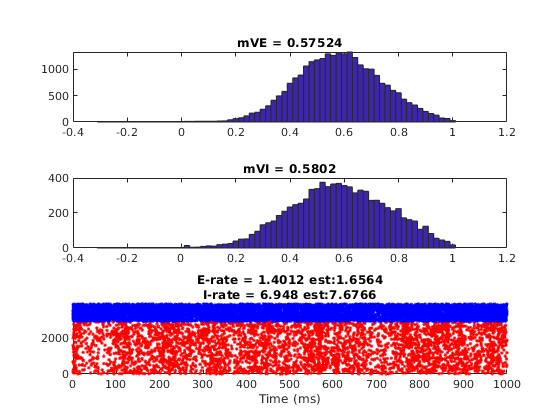

Elapsed time is 26.082025 seconds.
Elapsed time is 28.771478 seconds.


%% Network Simulation
T = 3000; SimulationT = 1000; dt = 0.1;
% E-to-E delay time
T_EEDly = 0.5; N_EEDly = floor(T_EEDly/dt);
T_IEDly = 0.5; N_IEDly = floor(T_IEDly/dt);
% Setup Results Recording
Fr_NW_BG      = zeros(2,1);
mV_NW_BG      = zeros(2,1);
%Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

% Compute Neuron Ind
% E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
% [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
% E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
% 
% I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
% [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
% I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);
% 
% N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2));
% N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

% Create sliding windows
sampleT = 200;
Sliding = 100;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% The initial states
InSs = load('Initials_L6.mat');
RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);
IEDlyRcd = sparse(N_I,N_IEDly);
%E_SpHis= []; I_SpHis=[];
E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('FrEs',   zeros(size(Wins(:,1))), 'FrIs',   zeros(size(Wins(:,1))),...
    'mVEs',   zeros(size(Wins(:,1))), 'mVIs',   zeros(size(Wins(:,1))));
NWTrace.VEDist =  cell(size(Wins(:,1)));
NWTrace.VIDist =  cell(size(Wins(:,1)));
NWTrace.Wins = Wins;

tic
for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
        oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
        oEEDlyRcd,oIEDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
        V1NetworkUpdate_Ver2_EEnIEDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
        EEDlyRcd,IEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
        C_EE_Fix,C_EI_Fix,C_IE_Fix,C_II_Fix,...
        S_EE,S_EI,S_IE,S_II,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
        dt,p_EEFail,...
        gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
        gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
        S_amb,lambda_E,lambda_I,rE_amb,rI_amb,...
        S_EL6,S_IL6,rE_L6,rI_L6); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd;
    
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
            ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
            'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
            ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
            'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
        
        fprintf(ParameterDisp)
        figure('Name','TestRaster');
        subplot 311
        hist(oVE,-0.3:0.02:1)
        title(['mVE = ' num2str(nanmean(VE_T))])
        %E_SpHis = [E_SpHis,sum(oSpE)];
        %axis([-0.4 1.1 0 6000])
        
        subplot 312
        hist(oVI,-0.3:0.02:1)
        title(['mVI = ' num2str(nanmean(VI_T))])
              
        %E_Ind = 10000:13000; I_Ind = 3300:4300;
        scatterE = find(ismember(E_Sp(:,1),E_Ind));
        scatterI = find(ismember(I_Sp(:,1),I_Ind));
        [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
        [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);
        
        WinSize = SimulationT;
        T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        
        f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
                                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                                    lambda_E,S_Elgn,rE_amb,S_amb,...
                                                    lambda_I,S_Ilgn,rI_amb,...
                                                    S_EL6,S_IL6,rE_L6,rI_L6,...
                                                    gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));
        %
        subplot 313
        hold on
        scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
        scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
        title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
        xlabel('Time (ms)')
        xlim(T_RateWindow)
        ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
        drawnow
        %pause
        %close(h)
        % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
        WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
        T_RateWindow = NWTrace.Wins(SampleInd,:);
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        
        NWTrace.FrEs(SampleInd) = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        NWTrace.FrIs(SampleInd) = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        NWTrace.mVEs(SampleInd) = nanmean(oVE(E_Ind));
        NWTrace.mVIs(SampleInd) = nanmean(oVI(I_Ind));
        
        NWTrace.VEDist{SampleInd} = oVE(E_Ind);
        NWTrace.VIDist{SampleInd} = oVI(I_Ind);
        
        SampleInd = SampleInd + 1;
        toc
    end
    
    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    
    if sum(isnan(oVE))>0.80*N_E
        BlowUp = true;
        disp('warning!: Network exploded')
        break
    end
    
    % the end of iteration
end

toc

NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp;


% If blown up, discard other recordings...
if ~BlowUp
    Fr_NW_BG     = [E_Rate;I_Rate];
    mV_NW_BG     = [nanmean(VE_T),nanmean(VI_T)];
    %Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;
end
% end of S_IE loop



## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_E = zeros(size(NnE.X),'single');
OD_EMap = zeros(n_E_HC*N_HC,'single');
for NeuInd = 1:length(NnE.X)
OD_E(NeuInd) = OrientDom(ODNum,NnE.X(NeuInd),NnE.Y(NeuInd),n_E_HC);
OD_EMap(NnE.Y(NeuInd),NnE.X(NeuInd)) = OD_E(NeuInd);
end

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
StimulusFac = 1;
lgnE_Drive = [60,50,42,50]*4/1e3 * StimulusFac;
lgnI_Drive = min(lgnE_Drive);
lambda_E_drive = lgnE_Drive(OD_E)';
lambda_I_drive = lgnI_Drive;

L6E_Drive = [50 35 20 35]*50/1e3 * StimulusFac;
rE_L6_Drive = L6E_Drive(OD_E)';
rI_L6_Drive = 3*L6E_Drive(OD_I)';


% Making Poisson here/Reading
T = 10000; dt = 0.1;
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);

%   [A,~,Times] = find(eventsN);
%   R = sparse(A,floor(Times/dt)+1,ones(size(A)),N,length(t));

Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
SimulationT = 5000; 
% E-to-E delay time
T_EEDly = .9; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .5; N_IEDly = floor(T_IEDly/dt);
T_EIDly = .5; N_EIDly = floor(T_EIDly/dt);
% % The initial states
% InSs = load('Initials_L6.mat');
% RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
% GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
% RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
% GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
% EEDlyRcd = sparse(N_E,N_EEDly);

% The initial states, for more simulation 
load(['LargeNWFixIni,mat'],'EndState');
%load('IniTest.mat');
RefTimeE = EndState{1}; VE = EndState{2}; SpE = EndState{3}; GE_ampa_R = EndState{4}; GE_nmda_R = EndState{5}; GE_gaba_R = EndState{6};
                                                             GE_ampa_D = EndState{7}; GE_nmda_D = EndState{8}; GE_gaba_D = EndState{9};
RefTimeI = EndState{10}; VI = EndState{11}; SpI = EndState{12}; GI_ampa_R = EndState{13}; GI_nmda_R = EndState{14}; GI_gaba_R = EndState{15};
                                                                GI_ampa_D = EndState{16}; GI_nmda_D = EndState{17}; GI_gaba_D = EndState{18};
if N_EEDly>=size(EndState{19},2)
EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
else
    EEDlyRcd = EndState{19}(:,1:N_EEDly);
end
if N_IEDly>=size(EndState{20},2)
IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
else
    IEDlyRcd = EndState{20}(:,1:N_IEDly);
end
EIDlyRcd = ones(N_E,N_EIDly);
% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

But to accelerate, we exclude L6 Current Input at first...

TPar = 10;
for TSec = 1:TPar
tic
for TimeN = 1:floor(T/dt/TPar)
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) + lambda_E_drive*dt*LGNCurInp) ...
                      + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                      + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive*dt*LGNCurInp) ...
                      + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                      + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
   V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                                        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                                                        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                                        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                                        EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          C_EE_Fix,C_EI_Fix,C_IE_Fix,C_II_Fix,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;
    
    
     
    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.02;
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs= I_Sp;
              
        SampleInd = SampleInd + 1
        %sum(isnan(oVE))/N_E
        FrENow = size(E_Sp,1)/N_E/sampleT*1000
        FrINow = size(I_Sp,1)/N_I/sampleT*1000
        toc        
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 5
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
text = ['DriveWkSp_FixPreSynN_T' num2str(TSec) 's.mat'];
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd, IEDlyRcd};
save([SaveFolder text],'NWTrace','EndState','-v7.3')

clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
end

SampleInd = 2

FrENow = 10.5510

FrINow = 38.6334

Elapsed time is 1.868144 seconds.


SampleInd = 3

FrENow = 9.8704

FrINow = 38.3420

Elapsed time is 3.199030 seconds.


SampleInd = 4

FrENow = 9.5976

FrINow = 37.9581

Elapsed time is 4.990253 seconds.


SampleInd = 5

FrENow = 9.4338

FrINow = 37.6529

Elapsed time is 6.323514 seconds.


SampleInd = 6

FrENow = 9.8163

FrINow = 38.4368

Elapsed time is 8.135944 seconds.


SampleInd = 7

FrENow = 9.3355

FrINow = 37.5095

Elapsed time is 9.367442 seconds.


SampleInd = 8

FrENow = 9.6083

FrINow = 38.0483

Elapsed time is 11.221246 seconds.


SampleInd = 9

FrENow = 9.3827

FrINow = 37.5812

Elapsed time is 12.549149 seconds.


SampleInd = 10

FrENow = 9.2867

FrINow = 37.3546

Elapsed time is 14.255672 seconds.


SampleInd = 11

FrENow = 9.1983

FrINow = 36.9222

Elapsed time is 15.479407 seconds.


SampleInd = 12

FrENow = 9.9916

FrINow = 38.5779

Elapsed time is 17.353931 seconds.


SampleInd = 13

FrENow = 9.3629

FrINow = 37.5280

Elapsed time is 18.690201 seconds.


SampleInd = 14

FrENow = 9.8118

FrINow = 38.4484

Elapsed time is 20.535198 seconds.


SampleInd = 15

FrENow = 9.7775

FrINow = 38.2588

Elapsed time is 21.797854 seconds.


SampleInd = 16

FrENow = 9.2311

FrINow = 37.1673

Elapsed time is 23.673325 seconds.


SampleInd = 17

FrENow = 9.6898

FrINow = 38.0900

Elapsed time is 25.067112 seconds.


SampleInd = 18

FrENow = 9.5290

FrINow = 37.9327

Elapsed time is 27.201463 seconds.


SampleInd = 19

FrENow = 9.4902

FrINow = 37.7153

Elapsed time is 28.610375 seconds.


SampleInd = 20

FrENow = 9.3400

FrINow = 37.4633

Elapsed time is 30.500019 seconds.


SampleInd = 21

FrENow = 10.1135

FrINow = 39.0172

Elapsed time is 31.886200 seconds.


Elapsed time is 31.886990 seconds.


SampleInd = 22

FrENow = 9.5306

FrINow = 37.7917

Elapsed time is 1.889933 seconds.


SampleInd = 23

FrENow = 9.8666

FrINow = 38.4553

Elapsed time is 3.253895 seconds.


SampleInd = 24

FrENow = 9.6380

FrINow = 38.1270

Elapsed time is 5.189802 seconds.


SampleInd = 25

FrENow = 9.4658

FrINow = 37.7500

Elapsed time is 6.528006 seconds.


SampleInd = 26

FrENow = 9.7996

FrINow = 38.3952

Elapsed time is 8.538303 seconds.


SampleInd = 27

FrENow = 9.5633

FrINow = 37.9813

Elapsed time is 9.804054 seconds.


SampleInd = 28

FrENow = 9.5229

FrINow = 37.8310

Elapsed time is 11.687901 seconds.


SampleInd = 29

FrENow = 9.4483

FrINow = 37.8194

Elapsed time is 13.042367 seconds.


SampleInd = 30

FrENow = 9.2974

FrINow = 37.4725

Elapsed time is 14.895427 seconds.


SampleInd = 31

FrENow = 9.5077

FrINow = 37.6437

Elapsed time is 16.190700 seconds.


SampleInd = 32

FrENow = 9.9291

FrINow = 38.5154

Elapsed time is 18.088335 seconds.


SampleInd = 33

FrENow = 9.3903

FrINow = 37.6830

Elapsed time is 19.374702 seconds.


SampleInd = 34

FrENow = 9.7142

FrINow = 38.1894

Elapsed time is 21.248575 seconds.


SampleInd = 35

FrENow = 9.5892

FrINow = 38.0206

Elapsed time is 22.593168 seconds.


SampleInd = 36

FrENow = 9.1289

FrINow = 37.1326

Elapsed time is 24.441384 seconds.


SampleInd = 37

FrENow = 10.0457

FrINow = 38.7652

Elapsed time is 25.796902 seconds.


SampleInd = 38

FrENow = 9.0558

FrINow = 36.9314

Elapsed time is 27.628113 seconds.


SampleInd = 39

FrENow = 9.9634

FrINow = 38.5016

Elapsed time is 28.949864 seconds.


SampleInd = 40

FrENow = 9.4986

FrINow = 37.7685

Elapsed time is 30.800804 seconds.


SampleInd = 41

FrENow = 9.7371

FrINow = 38.2842

Elapsed time is 32.144781 seconds.


Elapsed time is 32.145509 seconds.


SampleInd = 42

FrENow = 9.5199

FrINow = 37.8957

Elapsed time is 1.900055 seconds.


SampleInd = 43

FrENow = 9.2494

FrINow = 37.3315

Elapsed time is 3.218165 seconds.


SampleInd = 44

FrENow = 10.0198

FrINow = 38.7975

Elapsed time is 5.167298 seconds.


SampleInd = 45

FrENow = 8.9636

FrINow = 36.7418

Elapsed time is 6.391903 seconds.


SampleInd = 46

FrENow = 10.0975

FrINow = 38.7975

Elapsed time is 8.349843 seconds.


SampleInd = 47

FrENow = 9.3949

FrINow = 37.5789

Elapsed time is 9.725593 seconds.


SampleInd = 48

FrENow = 10.0076

FrINow = 38.7467

Elapsed time is 11.643032 seconds.


SampleInd = 49

FrENow = 9.3949

FrINow = 37.5419

Elapsed time is 12.990907 seconds.


SampleInd = 50

FrENow = 9.8301

FrINow = 38.6033

Elapsed time is 14.874546 seconds.


SampleInd = 51

FrENow = 9.4604

FrINow = 37.7662

Elapsed time is 16.218143 seconds.


SampleInd = 52

FrENow = 9.4162

FrINow = 37.6136

Elapsed time is 18.094916 seconds.


SampleInd = 53

FrENow = 9.1770

FrINow = 37.2482

Elapsed time is 19.424660 seconds.


SampleInd = 54

FrENow = 9.5511

FrINow = 37.8448

Elapsed time is 21.261924 seconds.


SampleInd = 55

FrENow = 9.5892

FrINow = 37.8009

Elapsed time is 22.586600 seconds.


SampleInd = 56

FrENow = 9.8232

FrINow = 38.4946

Elapsed time is 24.460272 seconds.


SampleInd = 57

FrENow = 9.6037

FrINow = 37.9535

Elapsed time is 25.688698 seconds.


SampleInd = 58

FrENow = 9.2882

FrINow = 37.2667

Elapsed time is 27.522811 seconds.


SampleInd = 59

FrENow = 9.5755

FrINow = 37.9581

Elapsed time is 28.860975 seconds.


SampleInd = 60

FrENow = 9.4825

FrINow = 37.7084

Elapsed time is 30.728411 seconds.


SampleInd = 61

FrENow = 9.4323

FrINow = 37.6321

Elapsed time is 32.000338 seconds.


Elapsed time is 32.001052 seconds.


SampleInd = 62

FrENow = 9.7607

FrINow = 38.3166

Elapsed time is 1.987519 seconds.


SampleInd = 63

FrENow = 9.7081

FrINow = 38.0876

Elapsed time is 3.320316 seconds.


SampleInd = 64

FrENow = 9.0436

FrINow = 36.9939

Elapsed time is 5.112773 seconds.


SampleInd = 65

FrENow = 9.6479

FrINow = 38.0160

Elapsed time is 6.474492 seconds.


SampleInd = 66

FrENow = 9.9238

FrINow = 38.4461

Elapsed time is 8.315884 seconds.


SampleInd = 67

FrENow = 9.3317

FrINow = 37.5905

Elapsed time is 9.673146 seconds.


SampleInd = 68

FrENow = 9.8583

FrINow = 38.5201

Elapsed time is 11.564101 seconds.


SampleInd = 69

FrENow = 9.1937

FrINow = 37.1742

Elapsed time is 12.878707 seconds.


SampleInd = 70

FrENow = 9.4726

FrINow = 37.6645

Elapsed time is 14.706052 seconds.


SampleInd = 71

FrENow = 9.4300

FrINow = 37.5812

Elapsed time is 16.049688 seconds.


SampleInd = 72

FrENow = 9.6350

FrINow = 37.9605

Elapsed time is 17.908993 seconds.


SampleInd = 73

FrENow = 9.2280

FrINow = 37.3060

Elapsed time is 19.208929 seconds.


SampleInd = 74

FrENow = 9.7630

FrINow = 38.0946

Elapsed time is 20.998169 seconds.


SampleInd = 75

FrENow = 9.4925

FrINow = 37.8287

Elapsed time is 22.292996 seconds.


SampleInd = 76

FrENow = 9.4734

FrINow = 37.5581

Elapsed time is 24.113705 seconds.


SampleInd = 77

FrENow = 9.9741

FrINow = 38.6657

Elapsed time is 25.424863 seconds.


SampleInd = 78

FrENow = 9.1023

FrINow = 37.0933

Elapsed time is 27.174772 seconds.


SampleInd = 79

FrENow = 10.1174

FrINow = 38.8739

Elapsed time is 28.413830 seconds.


SampleInd = 80

FrENow = 9.6251

FrINow = 38.1593

Elapsed time is 30.223252 seconds.


SampleInd = 81

FrENow = 8.8790

FrINow = 36.6817

Elapsed time is 31.385151 seconds.


Elapsed time is 31.385840 seconds.


SampleInd = 82

FrENow = 9.7607

FrINow = 38.2241

Elapsed time is 1.778704 seconds.


SampleInd = 83

FrENow = 9.1899

FrINow = 37.2066

Elapsed time is 2.985340 seconds.


SampleInd = 84

FrENow = 9.7851

FrINow = 38.1616

Elapsed time is 4.753336 seconds.


SampleInd = 85

FrENow = 9.3560

FrINow = 37.4332

Elapsed time is 5.996455 seconds.


SampleInd = 86

FrENow = 9.5008

FrINow = 37.7454

Elapsed time is 7.795109 seconds.


SampleInd = 87

FrENow = 9.6159

FrINow = 38.0391

Elapsed time is 9.109937 seconds.


SampleInd = 88

FrENow = 9.6129

FrINow = 37.9073

Elapsed time is 10.918547 seconds.


SampleInd = 89

FrENow = 9.6197

FrINow = 37.9766

Elapsed time is 12.170941 seconds.


SampleInd = 90

FrENow = 9.6319

FrINow = 37.9581

Elapsed time is 14.064415 seconds.


SampleInd = 91

FrENow = 9.5656

FrINow = 37.9975

Elapsed time is 15.364809 seconds.


SampleInd = 92

FrENow = 9.6967

FrINow = 38.1177

Elapsed time is 17.220495 seconds.


SampleInd = 93

FrENow = 9.4010

FrINow = 37.5812

Elapsed time is 18.543308 seconds.


SampleInd = 94

FrENow = 9.9588

FrINow = 38.5501

Elapsed time is 20.451511 seconds.


SampleInd = 95

FrENow = 9.8735

FrINow = 38.6565

Elapsed time is 21.781127 seconds.


SampleInd = 96

FrENow = 9.1510

FrINow = 37.1974

Elapsed time is 23.489126 seconds.


SampleInd = 97

FrENow = 9.6997

FrINow = 38.1061

Elapsed time is 24.734915 seconds.


SampleInd = 98

FrENow = 10.0472

FrINow = 38.8600

Elapsed time is 26.557850 seconds.


SampleInd = 99

FrENow = 9.1564

FrINow = 37.1650

Elapsed time is 27.833569 seconds.


SampleInd = 100

FrENow = 9.7036

FrINow = 38.2171

Elapsed time is 29.696922 seconds.


SampleInd = 101

FrENow = 10.2728

FrINow = 39.3248

Elapsed time is 31.034944 seconds.


Elapsed time is 31.035715 seconds.


SampleInd = 102

FrENow = 9.2737

FrINow = 37.4078

Elapsed time is 1.818768 seconds.


SampleInd = 103

FrENow = 9.3431

FrINow = 37.4633

Elapsed time is 3.149635 seconds.


SampleInd = 104

FrENow = 9.6152

FrINow = 37.8865

Elapsed time is 4.974649 seconds.


SampleInd = 105

FrENow = 9.5138

FrINow = 37.8610

Elapsed time is 6.320237 seconds.


SampleInd = 106

FrENow = 9.6533

FrINow = 38.0160

Elapsed time is 8.190420 seconds.


SampleInd = 107

FrENow = 9.6883

FrINow = 37.9882

Elapsed time is 9.398335 seconds.


SampleInd = 108

FrENow = 9.5610

FrINow = 37.9651

Elapsed time is 11.143991 seconds.


SampleInd = 109

FrENow = 9.3256

FrINow = 37.5581

Elapsed time is 12.378040 seconds.


SampleInd = 110

FrENow = 9.2623

FrINow = 37.2020

Elapsed time is 14.193517 seconds.


SampleInd = 111

FrENow = 10.1517

FrINow = 38.9941

Elapsed time is 15.524039 seconds.


SampleInd = 112

FrENow = 9.8590

FrINow = 38.6403

Elapsed time is 17.300023 seconds.


SampleInd = 113

FrENow = 9.0954

FrINow = 37.0794

Elapsed time is 18.607861 seconds.


SampleInd = 114

FrENow = 10.1257

FrINow = 38.9085

Elapsed time is 20.481649 seconds.


SampleInd = 115

FrENow = 9.1853

FrINow = 37.1326

Elapsed time is 21.817602 seconds.


SampleInd = 116

FrENow = 9.3941

FrINow = 37.6275

Elapsed time is 23.706489 seconds.


SampleInd = 117

FrENow = 9.2501

FrINow = 37.1534

Elapsed time is 24.927414 seconds.


SampleInd = 118

FrENow = 9.6091

FrINow = 37.9258

Elapsed time is 26.701622 seconds.


SampleInd = 119

FrENow = 10.1090

FrINow = 39.0565

Elapsed time is 27.960125 seconds.


SampleInd = 120

FrENow = 9.0825

FrINow = 36.9291

Elapsed time is 29.798143 seconds.


SampleInd = 121

FrENow = 9.5146

FrINow = 37.7015

Elapsed time is 31.117424 seconds.


Elapsed time is 31.118095 seconds.


SampleInd = 122

FrENow = 9.7828

FrINow = 38.3027

Elapsed time is 1.819022 seconds.


SampleInd = 123

FrENow = 9.2760

FrINow = 37.3060

Elapsed time is 3.133326 seconds.


SampleInd = 124

FrENow = 9.4696

FrINow = 37.5951

Elapsed time is 4.994711 seconds.


SampleInd = 125

FrENow = 9.6670

FrINow = 38.1316

Elapsed time is 6.346235 seconds.


SampleInd = 126

FrENow = 9.7859

FrINow = 38.3143

Elapsed time is 8.108391 seconds.


SampleInd = 127

FrENow = 9.7051

FrINow = 38.3143

Elapsed time is 9.379458 seconds.


SampleInd = 128

FrENow = 9.2265

FrINow = 37.1766

Elapsed time is 11.150843 seconds.


SampleInd = 129

FrENow = 9.5496

FrINow = 37.7177

Elapsed time is 12.454180 seconds.


SampleInd = 130

FrENow = 9.3835

FrINow = 37.5743

Elapsed time is 14.286455 seconds.


SampleInd = 131

FrENow = 10.2759

FrINow = 39.1467

Elapsed time is 15.676843 seconds.


SampleInd = 132

FrENow = 9.5519

FrINow = 37.9396

Elapsed time is 17.540305 seconds.


SampleInd = 133

FrENow = 9.4353

FrINow = 37.7500

Elapsed time is 18.827672 seconds.


SampleInd = 134

FrENow = 9.6891

FrINow = 38.1131

Elapsed time is 20.713744 seconds.


SampleInd = 135

FrENow = 9.2280

FrINow = 37.2436

Elapsed time is 22.031265 seconds.


SampleInd = 136

FrENow = 9.8407

FrINow = 38.4831

Elapsed time is 23.894723 seconds.


SampleInd = 137

FrENow = 9.3652

FrINow = 37.5026

Elapsed time is 25.203255 seconds.


SampleInd = 138

FrENow = 9.3637

FrINow = 37.4587

Elapsed time is 27.057591 seconds.


SampleInd = 139

FrENow = 9.7820

FrINow = 38.3443

Elapsed time is 28.377590 seconds.


SampleInd = 140

FrENow = 9.2638

FrINow = 37.3269

Elapsed time is 30.129509 seconds.


SampleInd = 141

FrENow = 9.6952

FrINow = 37.9651

Elapsed time is 31.492363 seconds.


Elapsed time is 31.493031 seconds.


SampleInd = 142

FrENow = 9.7135

FrINow = 38.0900

Elapsed time is 1.855803 seconds.


SampleInd = 143

FrENow = 9.4132

FrINow = 37.5442

Elapsed time is 3.155972 seconds.


SampleInd = 144

FrENow = 9.4848

FrINow = 37.7477

Elapsed time is 4.933546 seconds.


SampleInd = 145

FrENow = 9.4841

FrINow = 37.7801

Elapsed time is 6.200406 seconds.


SampleInd = 146

FrENow = 9.6693

FrINow = 38.2588

Elapsed time is 7.961913 seconds.


SampleInd = 147

FrENow = 9.2341

FrINow = 37.1419

Elapsed time is 9.183153 seconds.


SampleInd = 148

FrENow = 9.7340

FrINow = 38.2819

Elapsed time is 11.078207 seconds.


SampleInd = 149

FrENow = 9.5877

FrINow = 37.8448

Elapsed time is 12.304013 seconds.


SampleInd = 150

FrENow = 10.3788

FrINow = 39.4450

Elapsed time is 14.092571 seconds.


SampleInd = 151

FrENow = 9.2715

FrINow = 37.5142

Elapsed time is 15.290815 seconds.


SampleInd = 152

FrENow = 9.7378

FrINow = 38.3466

Elapsed time is 17.134047 seconds.


SampleInd = 153

FrENow = 9.1968

FrINow = 37.2459

Elapsed time is 18.446084 seconds.


SampleInd = 154

FrENow = 9.3797

FrINow = 37.4309

Elapsed time is 20.226123 seconds.


SampleInd = 155

FrENow = 9.6517

FrINow = 37.9512

Elapsed time is 21.584256 seconds.


SampleInd = 156

FrENow = 9.7287

FrINow = 38.1431

Elapsed time is 23.472218 seconds.


SampleInd = 157

FrENow = 9.9992

FrINow = 38.8854

Elapsed time is 24.855627 seconds.


SampleInd = 158

FrENow = 9.0725

FrINow = 37.1650

Elapsed time is 26.651940 seconds.


SampleInd = 159

FrENow = 9.6304

FrINow = 38.0298

Elapsed time is 27.951454 seconds.


SampleInd = 160

FrENow = 10.0762

FrINow = 38.8854

Elapsed time is 29.881657 seconds.


SampleInd = 161

FrENow = 9.6510

FrINow = 38.1177

Elapsed time is 31.208719 seconds.


Elapsed time is 31.209388 seconds.


SampleInd = 162

FrENow = 9.0085

FrINow = 36.8389

Elapsed time is 1.836957 seconds.


SampleInd = 163

FrENow = 9.7203

FrINow = 38.1709

Elapsed time is 3.160504 seconds.


SampleInd = 164

FrENow = 9.8628

FrINow = 38.5894

Elapsed time is 4.974117 seconds.


SampleInd = 165

FrENow = 9.7904

FrINow = 38.2888

Elapsed time is 6.252025 seconds.


SampleInd = 166

FrENow = 9.1716

FrINow = 37.1835

Elapsed time is 7.990708 seconds.


SampleInd = 167

FrENow = 10.1738

FrINow = 39.1560

Elapsed time is 9.411476 seconds.


SampleInd = 168

FrENow = 9.0741

FrINow = 37.1627

Elapsed time is 11.220469 seconds.


SampleInd = 169

FrENow = 9.4437

FrINow = 37.6529

Elapsed time is 12.507269 seconds.


SampleInd = 170

FrENow = 9.6037

FrINow = 38.0391

Elapsed time is 14.286757 seconds.


SampleInd = 171

FrENow = 9.7493

FrINow = 38.2495

Elapsed time is 15.556924 seconds.


SampleInd = 172

FrENow = 9.4155

FrINow = 37.6714

Elapsed time is 17.366741 seconds.


SampleInd = 173

FrENow = 9.6525

FrINow = 38.1177

Elapsed time is 18.640342 seconds.


SampleInd = 174

FrENow = 9.1952

FrINow = 37.1904

Elapsed time is 20.393802 seconds.


SampleInd = 175

FrENow = 9.5633

FrINow = 37.7917

Elapsed time is 21.765553 seconds.


SampleInd = 176

FrENow = 9.6647

FrINow = 38.1154

Elapsed time is 23.587486 seconds.


SampleInd = 177

FrENow = 9.5397

FrINow = 37.8448

Elapsed time is 24.907129 seconds.


SampleInd = 178

FrENow = 10.1890

FrINow = 39.2716

Elapsed time is 26.744448 seconds.


SampleInd = 179

FrENow = 9.1899

FrINow = 37.1904

Elapsed time is 27.986058 seconds.


SampleInd = 180

FrENow = 9.5816

FrINow = 37.9766

Elapsed time is 29.743271 seconds.


SampleInd = 181

FrENow = 9.3027

FrINow = 37.4078

Elapsed time is 30.962600 seconds.


Elapsed time is 30.963256 seconds.


SampleInd = 182

FrENow = 9.6578

FrINow = 37.9443

Elapsed time is 1.753235 seconds.


SampleInd = 183

FrENow = 9.4102

FrINow = 37.5558

Elapsed time is 2.990771 seconds.


SampleInd = 184

FrENow = 9.6990

FrINow = 38.1501

Elapsed time is 4.772746 seconds.


SampleInd = 185

FrENow = 9.5763

FrINow = 37.8795

Elapsed time is 6.094232 seconds.


SampleInd = 186

FrENow = 9.7759

FrINow = 38.1316

Elapsed time is 7.908951 seconds.


SampleInd = 187

FrENow = 9.1366

FrINow = 37.0794

Elapsed time is 9.237201 seconds.


SampleInd = 188

FrENow = 10.0442

FrINow = 38.7559

Elapsed time is 11.003555 seconds.


SampleInd = 189

FrENow = 9.1160

FrINow = 37.1372

Elapsed time is 12.236915 seconds.


SampleInd = 190

FrENow = 9.2212

FrINow = 37.1789

Elapsed time is 14.015858 seconds.


SampleInd = 191

FrENow = 9.9101

FrINow = 38.5201

Elapsed time is 15.267844 seconds.


SampleInd = 192

FrENow = 9.7066

FrINow = 38.1732

Elapsed time is 17.027896 seconds.


SampleInd = 193

FrENow = 9.3439

FrINow = 37.5072

Elapsed time is 18.272524 seconds.


SampleInd = 194

FrENow = 9.4353

FrINow = 37.5119

Elapsed time is 20.061614 seconds.


SampleInd = 195

FrENow = 9.3713

FrINow = 37.6159

Elapsed time is 21.289152 seconds.


SampleInd = 196

FrENow = 10.0312

FrINow = 38.7952

Elapsed time is 23.049089 seconds.


SampleInd = 197

FrENow = 9.0581

FrINow = 36.8783

Elapsed time is 24.351098 seconds.


SampleInd = 198

FrENow = 9.7241

FrINow = 38.1639

Elapsed time is 26.185470 seconds.


SampleInd = 199

FrENow = 9.4307

FrINow = 37.6228

Elapsed time is 27.514864 seconds.


SampleInd = 200

FrENow = 9.9764

FrINow = 38.7120

Elapsed time is 29.264905 seconds.


SampleInd = 201

FrENow = 9.6327

FrINow = 38.1154

Elapsed time is 30.462698 seconds.


Elapsed time is 30.463362 seconds.


Plot Spatial maps: load data

% read data, and get spike and mV
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
for TSec = 1:TPar
    text = ['DriveWkSp_FixPreSynN_T' num2str(TSec) 's.mat']
    load([SaveFolder text],'NWTrace');
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
end

text = 'DriveWkSp_FixPreSynN_T1s.mat'

text = 'DriveWkSp_FixPreSynN_T2s.mat'

text = 'DriveWkSp_FixPreSynN_T3s.mat'

text = 'DriveWkSp_FixPreSynN_T4s.mat'

text = 'DriveWkSp_FixPreSynN_T5s.mat'

text = 'DriveWkSp_FixPreSynN_T6s.mat'

text = 'DriveWkSp_FixPreSynN_T7s.mat'

text = 'DriveWkSp_FixPreSynN_T8s.mat'

text = 'DriveWkSp_FixPreSynN_T9s.mat'

text = 'DriveWkSp_FixPreSynN_T10s.mat'


WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
WinSize = StatWin(2) - StatWin(1);

S_EE = 0.024, S_EI = 0.0384, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.20223, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5


% Check soome time dependency
Opt = find(OD_E==1);
Worst = find(OD_E==3);
Nor = find(OD_E==2 | OD_E==4);

ShowWin = [8000 9000]

ShowWin =         8000        9000


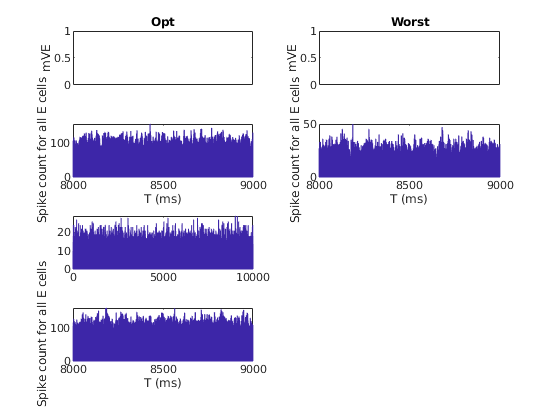

figure('Name','Theta')
subplot 423
hist(SpE(ismember(SpE(:,1),Opt),2),0:1:T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
xlim(ShowWin)
subplot 421
plot(StatWin(1:WinNum),nanmean(mVI(OD_I'==1,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

subplot 424
hist(SpE(ismember(SpE(:,1),Worst),2),0:1:T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
xlim(ShowWin)
subplot 422
plot(StatWin(1:WinNum),nanmean(mVI(OD_I'==3,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

subplot 427
hist(SpE(ismember(SpE(:,1),Nor),2),0:1:T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
xlim(ShowWin)
subplot 425
plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
ylabel('mVE')
set(gca,'xtick','')
xlim(ShowWin)

% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;
% OptOne = find(OD_EMapTry(:)==1);
% hist(SpE(ismember(SpE(:,1),OptOne),2),0:1:T)

Plot Spatial maps: Plot

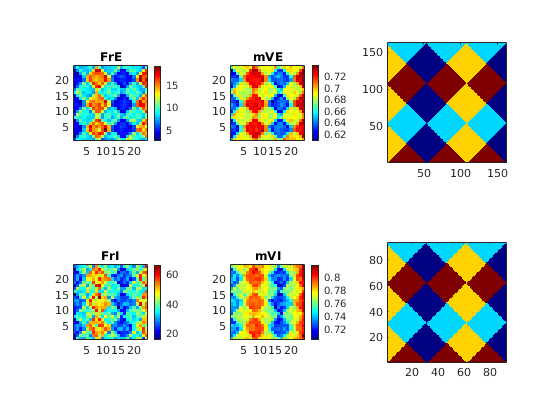

WinSize = 7500;
Window = [T-WinSize T];
EffSize = Window(2)-max(0,Window(1));

h = figure('Name','Field_f&V');

% PixelNum per HC
NPixX = 8; %10
NPixY = 8;

subplot 231
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

[FrEPixMat,NnEPixel] = NeuVec2Pixel(FrE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 232
mVE_temp = nanmean(mVE(:,SmallWinRange),2);
mVE_Map = reshape(mVE_temp,N_HC*n_E_HC,N_HC*n_E_HC);

[mVEPixMat,~] = NeuVec2Pixel(mVE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(mVEPixMat); title('mVE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 233
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')


% end of 500ms plot

    


%save('DriveWkSp.mat')

## MF linear equation for pixels: 1 Matrices

FrEPixVec = reshape(FrEPixMat,NPixX*N_HC*NPixY*N_HC,1);
FrIPixVec = reshape(FrIPixMat,NPixX*N_HC*NPixY*N_HC,1);
mVEPixVec = reshape(mVEPixMat,NPixX*N_HC*NPixY*N_HC,1);
mVIPixVec = reshape(mVIPixMat,NPixX*N_HC*NPixY*N_HC,1);
% First, get connectivity matrix between Pixels
C_EE_Pixel = zeros(length(FrEPixVec));
C_EI_Pixel = zeros(length(FrEPixVec));
C_IE_Pixel = zeros(length(FrEPixVec));
C_II_Pixel = zeros(length(FrEPixVec));
% look into std as well
C_EE_Pixelstd = zeros(length(FrEPixVec));
C_EI_Pixelstd = zeros(length(FrEPixVec));
C_IE_Pixelstd = zeros(length(FrEPixVec));
C_II_Pixelstd = zeros(length(FrEPixVec));
tic
AA = length(FrEPixVec);
parfor PixIndPost = 1:AA
    for PixIndPre = 1:AA
        C_EE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EE(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EI(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_IE(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixel(PixIndPost,PixIndPre) = mean(sum(C_II(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_EE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EE(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EI(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_IE(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_II(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
    end    
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


toc

Elapsed time is 61.818476 seconds.


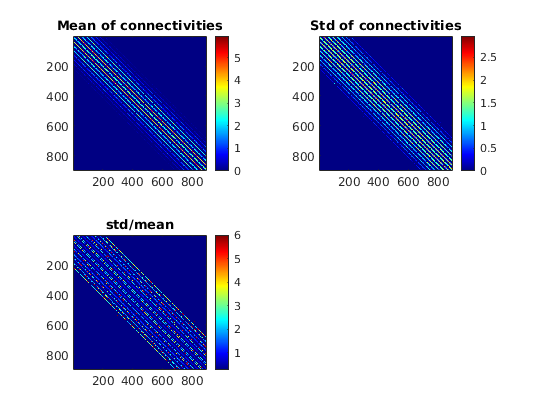

C_EE_Pixel_Us = sparse(C_EE_Pixel);
C_IE_Pixel_Us = sparse(C_IE_Pixel);
C_EI_Pixel_Us = sparse(C_EI_Pixel);
C_II_Pixel_Us = sparse(C_II_Pixel);

% Present connectivity mats
figure
subplot 221
imagesc(C_EE_Pixel)
colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_EE_Pixelstd)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_EE_Pixelstd./C_EE_Pixel)
axis square
colorbar
title('std/mean')

MF linear equation for pixels: 2 MF Eqns

% Mats
MatEE = (S_EE*(1-p_EEFail))*C_EE_Pixel_Us.*(Ve-repmat(mVEPixVec,1,NPixX*N_HC*NPixY*N_HC)); % Need Ref here??
MatEI = S_EI *              C_EI_Pixel_Us.*(Vi-repmat(mVEPixVec,1,NPixX*N_HC*NPixY*N_HC));
MatIE = S_IE *              C_IE_Pixel_Us.*(Ve-repmat(mVIPixVec,1,NPixX*N_HC*NPixY*N_HC));
MatII = S_II *              C_II_Pixel_Us.*(Vi-repmat(mVIPixVec,1,NPixX*N_HC*NPixY*N_HC));
ConnMat = [MatEE,MatEI;MatIE,MatII];
% Leak
LeakE = gL_E * (0-mVEPixVec) * 1e3;
LeakI = gL_I * (0-mVIPixVec) * 1e3;
LeakV = [LeakE;LeakI];
% Ext
lambda_E_Pixel = zeros(size(mVEPixVec));
for PixInd = 1:length(FrEPixVec)
    lambda_E_Pixel(PixInd) = mean(lambda_E_drive(NnEPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive;
ExtE = (lambda_E_Pixel*S_Elgn + rE_amb*S_amb + rE_L6*S_EL6).*(Ve-mVEPixVec) * 1e3;
ExtI = (lambda_I_Pixel*S_Ilgn + rI_amb*S_amb + rI_L6*S_IL6) *(Ve-mVIPixVec) * 1e3;
ExtV = [ExtE;ExtI];
% Ref Vec
RefE = 1-FrEPixVec*tau_ref/1e3;
RefI = 1-FrIPixVec*tau_ref/1e3;
RefM = sparse(diag([RefE;RefI]));
% L4 Frs
Fr_L4 = [FrEPixVec;FrIPixVec];

% MF Equations:
Fr_MF = RefM * (ConnMat*Fr_L4 + ExtV + LeakV);
Fr_MFinv = (sparse(eye(2*NPixX*N_HC*NPixY*N_HC))-RefM*ConnMat)^-1 * (RefM * ( ExtV + LeakV));

% Err
FrErr = Fr_MFinv - Fr_L4;

figure('Name','MF and Real Fr')
a1 = subplot (241);
PS = get(a1,'Position');
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a1,'Position',PS)

a5 = subplot (245);
PS = get(a5,'Position');
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a5,'Position',PS)

a2 = subplot (242);
PS = get(a2,'Position');
FrEPixMat_MF = reshape(Fr_MFinv(1:length(FrEPixVec)),NPixY*N_HC,NPixX*N_HC)

FrEPixMat_MF =    24.0584   20.6357   16.2640   17.0789   19.8834   17.9040   20.2059   14.7228   14.3790   21.2880   17.1811   21.6281   20.5791   16.3467   18.7380   17.7322   15.1336   20.0761   12.7486   16.2750   11.0080   12.7791   15.0993   17.9279   22.5989   17.6102   19.7515   19.5041   22.5183   36.5042
   23.6728   15.6005    5.5058   10.9836    8.3703    8.7473    5.8466   14.2955    8.8917    5.0909    9.3820   11.0271   12.9287    8.9429    8.9217   13.4992   13.5756    2.8034    6.9596    6.4266    7.9976    8.2144    0.6151    4.3764   16.3531    7.3237   12.3636   20.2032   17.2516   21.2845
   23.8670    4.1196    4.6874    5.1684    4.9333   13.6883    7.5052    8.9839    9.2852    4.6596    9.5751    8.9535   11.0110   13.0811   10.3213    8.4273    2.0123    6.8752    6.4728    4.5741    4.3300    7.4070    3.5845    1.8618    7.1604    5.9493   13.3174   10.4351    5.9736   17.7721
   13.5991    6.9359    8.7884    4.4979    8.3708   12.8174    9.0458   15.3833  

imagesc(FrEPixMat_MF); title('FrE_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a2,'Position',PS)

a6 = subplot (246);
PS = get(a6,'Position');
FrIPixMat_MF = reshape(Fr_MFinv(length(FrEPixVec)+1:end),NPixY*N_HC,NPixX*N_HC)

FrIPixMat_MF =    78.1495   25.5058   36.4239   30.2737   61.3917   66.5800   40.2570   46.1230   61.3596   31.6703   61.8576   35.4678   63.8254   62.1887   57.6487   44.2903   48.8810   13.6597   20.0126   41.8762   40.3363   14.4840   41.0890   37.1393   45.5495   37.7306   49.9789   52.8155   25.7180   61.4474
   48.0080   17.7839    8.9702   42.6235   12.6598   25.0067   45.1747   36.2810   -0.8440   34.7038   25.6147   32.4348    5.1414   35.5324   23.2195   17.8842   17.3805   40.0214   18.0471   24.8823   36.4983   36.2804   21.1810   23.6942   31.4460   33.8504   26.4218   36.2104   27.7398   15.9130
   22.3060   54.8850   37.1689   -4.8430    2.3981   21.3893   22.8472   39.9601   31.0071   25.1228   31.3395   27.2445   -1.9292   50.0204   10.3718   16.5727    2.2931   58.9738   31.8223   10.7296   38.5664   14.4340   12.6381    6.5416   20.9094   50.9795    3.0215   32.2900   32.0931   59.4180
   36.4357   20.6550   17.5830   42.6675   19.0921   30.4739   10.7990   19.4154  

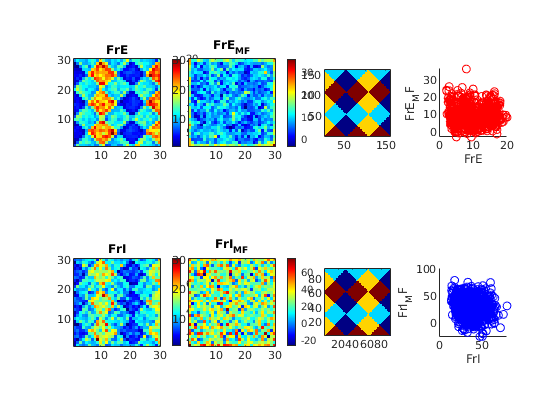

imagesc(FrIPixMat_MF); title('FrI_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a6,'Position',PS)

subplot 243
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 247
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

subplot 244
scatter(FrEPixVec,Fr_MFinv(1:NPixX*N_HC*NPixY*N_HC),'ro')
% axis([0 40 0 40])
axis square
xlabel('FrE'); ylabel('FrE_MF')

subplot 248
scatter(FrIPixVec,Fr_MFinv(NPixX*N_HC*NPixY*N_HC+1:end),'bo')
% axis([0 120 0 120])
axis square
xlabel('FrI'); ylabel('FrI_MF')

Result not very good. On the other hand, should concern real input since we are only averaging from 25/8 neurons?

Check code: Mistakes in row and column?